%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Preliminary Parameters: Please do not change!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Color map used in coloring arrows on graph
jetColor = [0         0    0.5625;...
                     0         0    0.6250; ...
                     0         0    0.6875;...
                     0         0    0.7500;...
                     0         0    0.8125;...
                     0         0    0.8750;...
                     0         0    0.9375;...
                     0         0    1.0000;...
                     0    0.0625    1.0000;...
                     0    0.1250    1.0000;...
                     0    0.1875    1.0000;...
                     0    0.2500    1.0000;...
                     0    0.3125    1.0000;...
                     0    0.3750    1.0000;...
                     0    0.4375    1.0000;...
                     0    0.5000    1.0000;...
                     0    0.5625    1.0000;...
                     0    0.6250    1.0000;...
                     0    0.6875    1.0000;...
                     0    0.7500    1.0000;...
                     0    0.8125    1.0000;...
                     0    0.8750    1.0000;...
                     0    0.9375    1.0000;...
                     0    1.0000    1.0000;...
                0.0625    1.0000    0.9375;...
                0.1250    1.0000    0.8750;...
                0.1875    1.0000    0.8125;...
                0.2500    1.0000    0.7500;...
                0.3125    1.0000    0.6875;...
                0.3750    1.0000    0.6250;...
                0.4375    1.0000    0.5625;...
                0.5000    1.0000    0.5000;...
                0.5625    1.0000    0.4375;...
                0.6250    1.0000    0.3750;...
                0.6875    1.0000    0.3125;...
                0.7500    1.0000    0.2500;...
                0.8125    1.0000    0.1875;...
                0.8750    1.0000    0.1250;...
                0.9375    1.0000    0.0625;...
                1.0000    1.0000         0;...
                1.0000    0.9375         0;...
                1.0000    0.8750         0;...
                1.0000    0.8125         0;...
                1.0000    0.7500         0;...
                1.0000    0.6875         0;...
                1.0000    0.6250         0;...
                1.0000    0.5625         0;...
                1.0000    0.5000         0;...
                1.0000    0.4375         0;...
                1.0000    0.3750         0;...
                1.0000    0.3125         0;...
                1.0000    0.2500         0;...
                1.0000    0.1875         0;...
                1.0000    0.1250         0;...
                1.0000    0.0625         0;...
                1.0000         0         0;...
                0.9375         0         0;...
                0.8750         0         0;...
                0.8125         0         0;...
                0.7500         0         0;...
                0.6875         0         0;...
                0.6250         0         0;...
                0.5625         0         0;...
                0.5000         0         0];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%User Inputs, Please Adjust to your preference!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%First Material: Water ~= Blood
speedLong1 = 0.1458; %m/s
density1 = 1; %g/cm^3
z1l = speedLong1*density1;
degIn = 27.135; %Incident angle (degrees) -> Do not let exceed 89.9 degrees, or fall below 0 (physically unrealistic)

%Second Material: Bone
speedLong2 = 0.3198; %m/s
density2 = 1.99; %g/cm^3
z2l = speedLong2*density2;

%See what the critical angle is based on the input parameters
critical_angle = asind(speedLong1/speedLong2)

critical_angle = 27.1235

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Reflection/Refraction Angle and Intensity Calculations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%First I check the transLongue c2/c1*sin(degIn) to see if the critical angle has been exceeded
transLong = sind(degIn)/speedLong1*speedLong2;

%First Critical Angle -> Only shear wave transmits
if transLong>1
    degOut = 90
    Rf = 1
    Tf = 0
else
    degOut = asind(transLong)
    Z2theta1 = z2l*cosd( degIn );
    Z1theta2 = z1l*cosd( degOut );
    Rf = (Z2theta1 - Z1theta2).^2/(Z2theta1 + Z1theta2).^2
    Tf = 4*(Z2theta1 * Z1theta2)/(Z2theta1 + Z1theta2).^2 %You can change transmission formula to this to see they are equivical formulas
    %Tf = 1 - Rf %Uncomment to see equal to above equation
end

degOut = 90

Rf = 1

Tf = 0


%%%%%%%%%%
%Draw Axes
%%%%%%%%%%

%Draw axes lines
figure; %Define a new figure
hold on; %This allows us to draw on the same figure until hold is turned off
line([-1 1], [0 0],'LineWidth',2,'Color','k'); %x-axis
line([0 0], [-1 1],'LineWidth',2,'LineStyle','--'); %y-axis

%%%%%%%%%%%%%%%%%%%%%%%
%Draw Arrows and Angles
%%%%%%%%%%%%%%%%%%%%%%%

%First, I adjust the calculated angles so the arrows will appear in the correct quadrant of the graph
inc = 90+degIn %Incident Angle->second quadrant

inc = 117.1350

rfl = 90-degIn %Reflected Angle->first quadrant

rfl = 62.8650

rfr = 270+degOut %Refracted Longitudinal Angle->fourth quadrant

rfr = 360

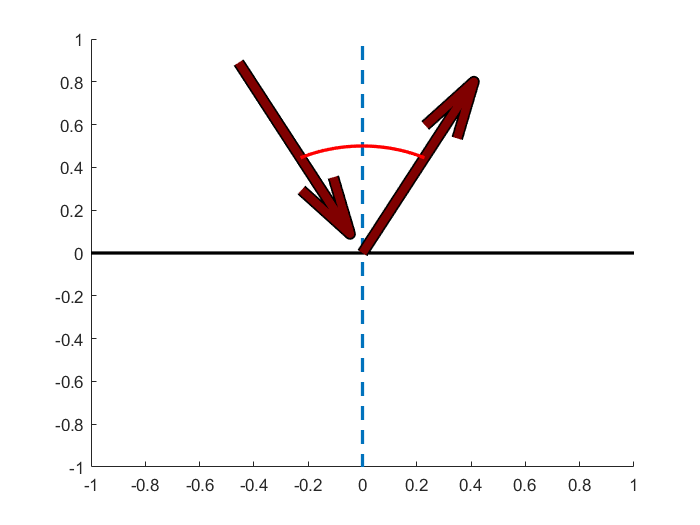

r = 0.5;
 
%Define a line covering how far I want the angles to draw
theta_rfl = linspace(rfl,inc,100); %Angle line between reflected and incident
theta_rfr = linspace(270,rfr,100); %Angle between y-axis and Longitudinal Transmitted


%The arrow's color will be based on the reflected and refracted intensity transLongues
rflRGB = jetColor(round(Rf*63)+1,:);
rfrRGB = jetColor(round(Tf*63)+1,:);


%Draw Incident Arrow
%I outline the longitudinal waves in black by drawing a larger black arrow first
quiver(cosd(inc), sind(inc), -cosd(inc), -sind(inc), ...
'Color','k', ...
'LineWidth',7, ...
'MaxHeadSize',1);
quiver(cosd(inc), sind(inc), -cosd(inc), -sind(inc), ...
'Color',jetColor(end,:), ...
'LineWidth',5, ...
'MaxHeadSize',1);

%Draw Reflected Angle
if Rf > 0.01 % If the transLongue is under 1% I don't bother drawing that arrow for almost no power is retained in that wave
     quiver(0, 0, cosd(rfl), sind(rfl), ...
    'Color','k', ...
    'LineWidth',7, ...
    'MaxHeadSize',1);
    quiver(0, 0, cosd(rfl), sind(rfl), ...
    'Color',rflRGB, ...
    'LineWidth',5, ...
    'MaxHeadSize',1);
    %Draw Angle Line
    plot(r*cosd(theta_rfl),r*sind(theta_rfl),'LineWidth',2,'Color','r');
end


%Transmitted Longitude Arrow
if Tf > 0.01
    quiver(0, 0, cosd(rfr), sind(rfr), ...
    'Color','k', ...
    'LineWidth',7, ...
    'MaxHeadSize',1);
    quiver(0, 0, cosd(rfr), sind(rfr), ...
    'Color',rfrRGB, ...
    'LineWidth',5, ...
    'MaxHeadSize',1);
    %Draw Angle Line
    plot(r*cosd(theta_rfr),r*sind(theta_rfr),'LineWidth',2,'Color','b');
end
